 %read audio..... Fs = 8KHZ
[y, Fs] = audioread('music.mp3');
%figure;
%plot(f, Y);
%xlabel('f (Hz)'); ylabel('amplitute');title('spectrum of the message before resampling')



%resample at Fs = 48KHZ.
[P,Q] = rat(48e3/Fs);   
y = resample(y, P, Q);
FsOriginal = Fs

FsOriginal = 44100

Fs = 48e3;
%playerObj = audioplayer(y,Fs);
%start = 1;
%stop = playerObj.SampleRate * 5;

%play(playerObj,[start,stop]);


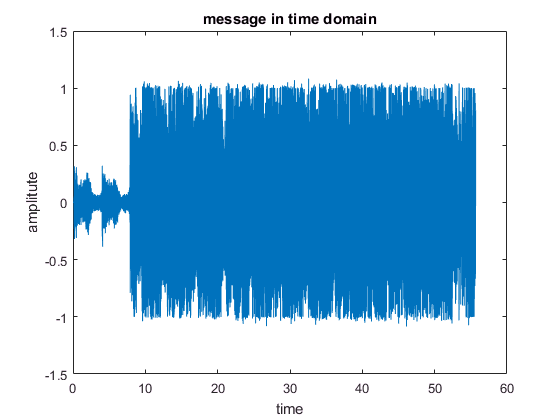


%converting from stereo to mono by removing the second channel if existed.
y = y(:,1)';
%%
t = linspace(0, length(y)/Fs, length(y));

figure;
plot(t, y);
xlabel('time'); ylabel('amplitute');title('message in time domain');

%converting the signal from time domain to frequency domain
%using Fast Fourier Transform
Y = fft(y);
Y = fftshift(Y);
f = linspace(-Fs/2, Fs/2, length(Y));
figure;
plot(f, Y);

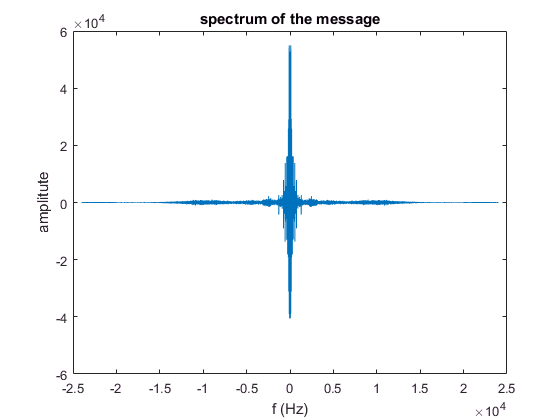

xlabel('f (Hz)'); ylabel('amplitute');title('spectrum of the message')



%applying the bandpass filter @ 4KHz
Y_filtered = Y;

Y_filtered(find(f >= 4000)) = 0;
Y_filtered(find(f <= -4000)) = 0;

f_filtered = linspace(-Fs/2, Fs/2, length(Y_filtered));

figure;
plot(f_filtered, Y_filtered);

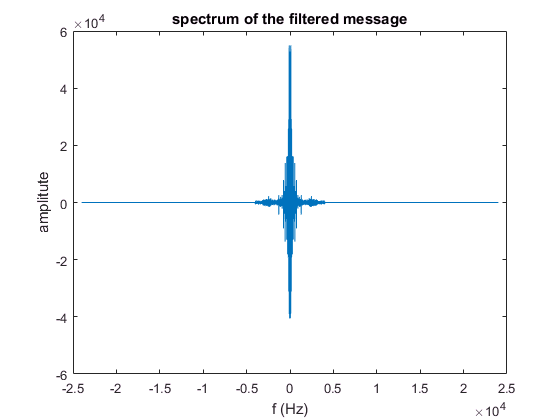

xlabel('f (Hz)'); ylabel('amplitute');title('spectrum of the filtered message');

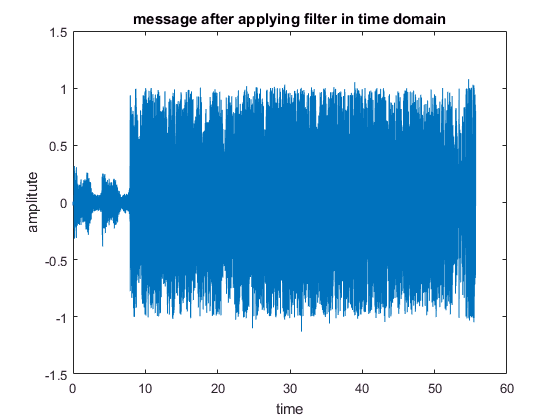


y_filtered = ifft(ifftshift(Y_filtered));
%y_filtered = y_filtered(1: 100);

t = linspace(0, length(y_filtered)/Fs, length(y_filtered));

figure;
plot(t, y_filtered);
xlabel('time'); ylabel('amplitute');title('message after applying filter in time domain');

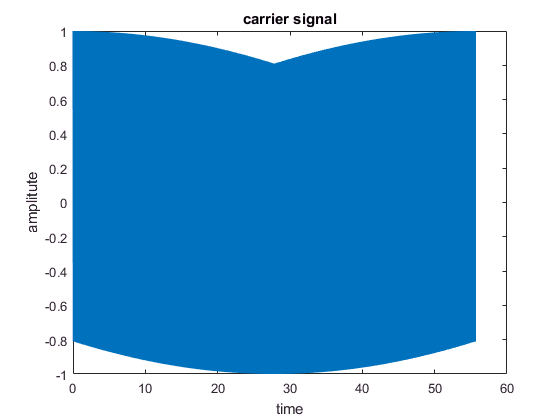


%sound(y_filtered, Fs);   
%%
%DSB-SC
Fc = 1e5;   %carrier frequency Fc

%resample at Fs = 5*Fc
[P,Q] = rat((5*Fc)/Fs);   
y_filtered = resample(y_filtered, P, Q);
Fs = 5*Fc;


%carrier
t = linspace(0, length(y_filtered)/Fs, length(y_filtered));
carrier = cos(2 * pi * Fc * t);

figure;
plot(t, carrier);
xlabel('time'); ylabel('amplitute');title('carrier signal');

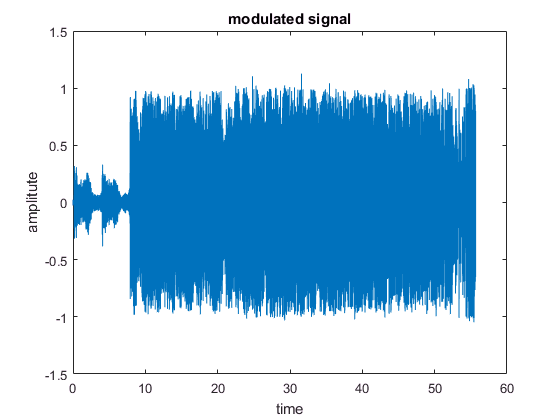



DSB_SC = y_filtered .* carrier;

figure;
plot(t, DSB_SC);
xlabel('time'); ylabel('amplitute');title('modulated signal');


% demodulating
%%%%%%% SNR = 0 %%%%%%%

dsbsc_with_noise_0 = awgn(DSB_SC,0);

dsbsc_demod_carrier  = dsbsc_with_noise_0.*carrier;
f_dsbsc_demod_carrier = fftshift(fft(dsbsc_demod_carrier));

demod_lpf  = [zeros(1,13813745) ones(1,200000) zeros(1,13813745)];
filtered_f_dsbsc_demod_carrier = f_dsbsc_demod_carrier.*demod_lpf;
filtered_dsbsc  = ifft(ifftshift(filtered_f_dsbsc_demod_carrier));

filtered_dsbsc  = resample(filtered_dsbsc,FsOriginal,Fc);
f_filtered_dsbsc = fftshift(fft(filtered_dsbsc));
new_t    = linspace(0,(length(filtered_dsbsc)/FsOriginal),length(filtered_dsbsc));
new_freq = linspace(-FsOriginal/2,FsOriginal/2,length(filtered_dsbsc));


figure;
plot(new_t,filtered_dsbsc);title 'Demodulated DSB-SC signal (SNR = 0)';

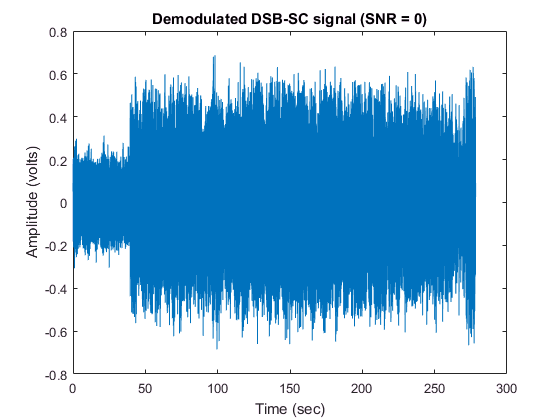

xlabel 'Time (sec)';ylabel 'Amplitude (volts)';

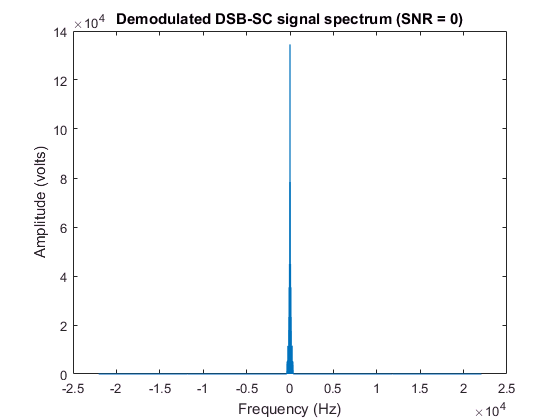

plot(new_freq,abs(f_filtered_dsbsc));title 'Demodulated DSB-SC signal spectrum (SNR = 0)';
xlabel 'Frequency (Hz)';ylabel 'Amplitude (volts)';



%%%%%%% SNR = 10 %%%%%%%

dsbsc_with_noise_10 = awgn(DSB_SC,10);

dsbsc_demod_carrier  = dsbsc_with_noise_10.*carrier;
f_dsbsc_demod_carrier = fftshift(fft(dsbsc_demod_carrier));

demod_lpf  = [zeros(1,13813745) ones(1,200000) zeros(1,13813745)];
filtered_f_dsbsc_demod_carrier = f_dsbsc_demod_carrier.*demod_lpf;
filtered_dsbsc  = ifft(ifftshift(filtered_f_dsbsc_demod_carrier));

filtered_dsbsc  = resample(filtered_dsbsc,FsOriginal,Fc);
f_filtered_dsbsc = fftshift(fft(filtered_dsbsc));
new_t    = linspace(0,(length(filtered_dsbsc)/FsOriginal),length(filtered_dsbsc));
new_freq = linspace(-FsOriginal/2,FsOriginal/2,length(filtered_dsbsc));


figure;
plot(new_t,filtered_dsbsc);title 'Demodulated DSB-SC signal (SNR = 10)';

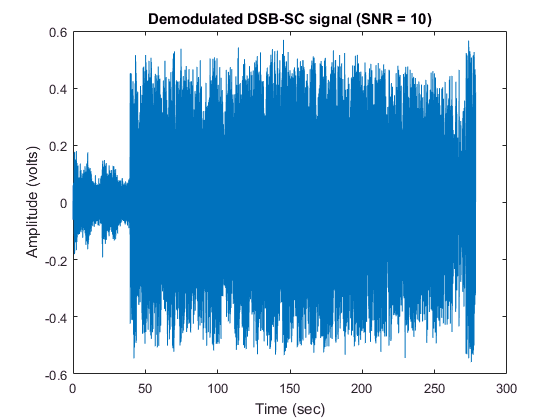

xlabel 'Time (sec)';ylabel 'Amplitude (volts)';

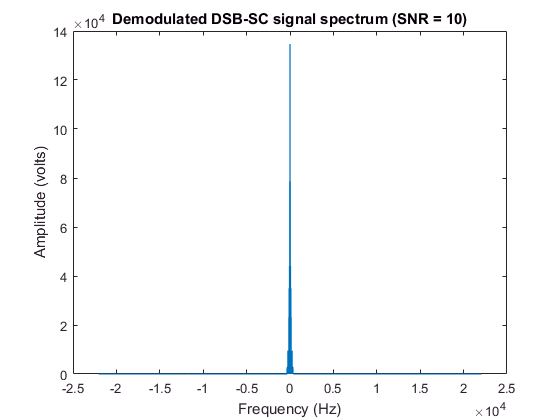

plot(new_freq,abs(f_filtered_dsbsc));title 'Demodulated DSB-SC signal spectrum (SNR = 10)';
xlabel 'Frequency (Hz)';ylabel 'Amplitude (volts)';



%%%%%%% SNR = 30 %%%%%%%

dsbsc_with_noise_30 = awgn(DSB_SC,30);

dsbsc_demod_carrier  = dsbsc_with_noise_30.*carrier;
f_dsbsc_demod_carrier = fftshift(fft(dsbsc_demod_carrier));

demod_lpf  = [zeros(1,13813745) ones(1,200000) zeros(1,13813745)];
filtered_f_dsbsc_demod_carrier = f_dsbsc_demod_carrier.*demod_lpf;
filtered_dsbsc  = ifft(ifftshift(filtered_f_dsbsc_demod_carrier));

filtered_dsbsc  = resample(filtered_dsbsc,FsOriginal,Fc);
f_filtered_dsbsc = fftshift(fft(filtered_dsbsc));
new_t    = linspace(0,(length(filtered_dsbsc)/FsOriginal),length(filtered_dsbsc));
new_freq = linspace(-FsOriginal/2,FsOriginal/2,length(filtered_dsbsc));


figure;
plot(new_t,filtered_dsbsc);title 'Demodulated DSB-SC signal (SNR = 30)';

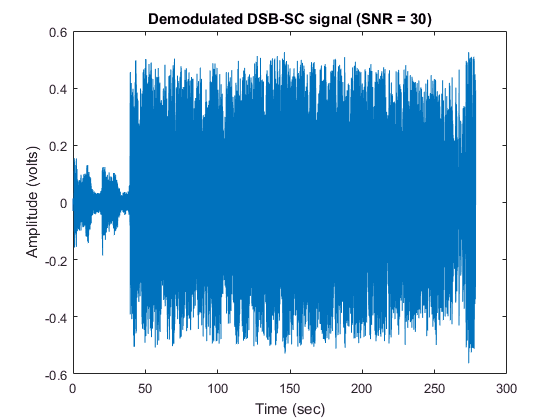

xlabel 'Time (sec)';ylabel 'Amplitude (volts)';

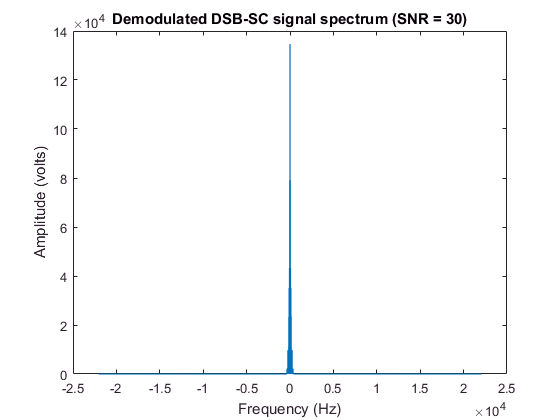

plot(new_freq,abs(f_filtered_dsbsc));title 'Demodulated DSB-SC signal spectrum (SNR = 30)';
xlabel 'Frequency (Hz)';ylabel 'Amplitude (volts)';